clc;
close all;
clear all;


load("GISR-Net.mat")


fullData = readtable("Test.csv");
imageData = fullData.Images;
nImg = height(imageData)

nImg = 50


testimds = imageDatastore(imageData);
testDSI = fullData.Original_DSI;

testds = augmentedImageDatastore([224 224],testimds);

New_Test_Predicted = abs(predict(ccnet,testds));

New_Test_Pred_mae = errperf(testDSI,New_Test_Predicted,'mae')

New_Test_Pred_mae = single
0.0661

New_Test_Pred_rmse = errperf(testDSI,New_Test_Predicted,'rmse')

New_Test_Pred_rmse = single
0.0814

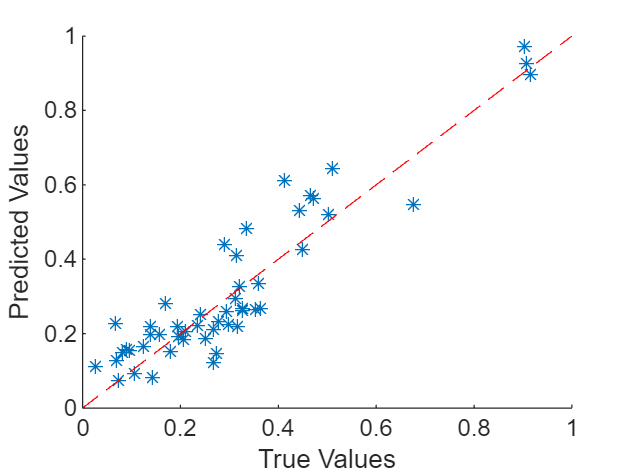

figure
scatter(testDSI,New_Test_Predicted,'*')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 1], [0 1],'r--')

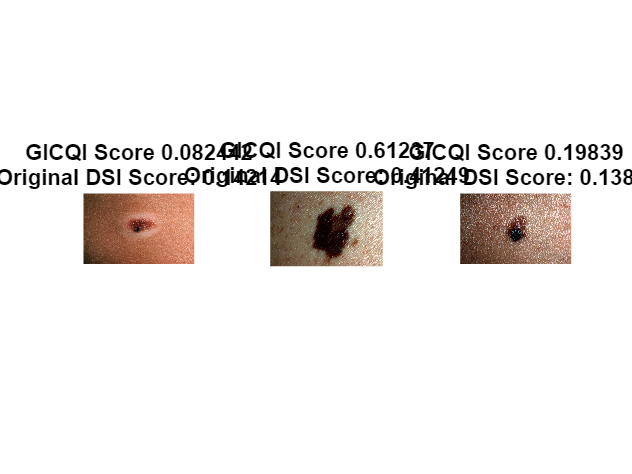

figure
t = tiledlayout(1,3);
idx1 = randperm(nImg,1);
displayImageAndScores(t,readimage(testimds,idx1), ...
    testDSI(idx1),"GICQI Score "+ New_Test_Predicted(idx1))
idx2 = randperm(nImg,1);
displayImageAndScores(t,readimage(testimds,idx2), ...
    testDSI(idx2),"GICQI Score "+ New_Test_Predicted(idx2))
idx3 = randperm(nImg,1);
displayImageAndScores(t,readimage(testimds,idx3), ...
    testDSI(idx3),"GICQI Score "+ New_Test_Predicted(idx3))

analyzeNetwork(ccnet)